# Solution of the Heat Equation with non homogeneous, time varying Dirichlet boundary conditions using FEM

**ReadMe: ** Files graficopcg.mlx and graficopcg_jac.mlx only contain the plot of convergence in the same graph for all the meshes with different preconditioners, so femc.mlx  does not depend on those to be run.

format long g
%solution on a very fine grid to compute error
sol_ref = load('C:\Users\UTENTE\OneDrive\Documents\MATLAB\solRef.dat.txt'); 
xRef=sol_ref(:,1);
yRef=sol_ref(:,2);
uRef=sol_ref(:,3);
interp = scatteredInterpolant(xRef, yRef, uRef);

mesh_num = 0:4; 
for mesh = 1 : length(mesh_num)  
ind=mesh_num(mesh);
topology = load(sprintf('C:\\Users\\UTENTE\\OneDrive\\Documents\\MATLAB\\mesh%i.topol', ind)); 
coordinates = load(sprintf('C:\\Users\\UTENTE\\OneDrive\\Documents\\MATLAB\\mesh%i.coord', ind));
boundary_conditions = load(sprintf('C:\\Users\\UTENTE\\OneDrive\\Documents\\MATLAB\\mesh%i.bound', ind));
track= load(sprintf('C:\\Users\\UTENTE\\OneDrive\\Documents\\MATLAB\\mesh%i.track',  ind));
trace= load(sprintf('C:\\Users\\UTENTE\\OneDrive\\Documents\\MATLAB\\mesh%i.trace',  ind));

x= coordinates(:,1);
y=coordinates(:,2);
sol = zeros(size(coordinates, 1), 1);
for i=1:size(coordinates, 1)
   sol(i) = interp(x(i), y(i));
end

    num_track = length(track);
    node_indices = trace(:, 1);
    arc_lengths = trace(:, 2);
    solutions_at_times = zeros(length(node_indices), 4);
    
    [H, M] = compute_local_matrices(topology, coordinates);
    H=sparse(H);
    M=sparse(M);
    % Initialize  solution vector (u) to zeros
    num_nodes = size(coordinates, 1);
    
    %u_chol= zeros(num_nodes, 1);
    delta_t = 0.02;
    t_max = 10;
    theta = 0.5;
    num_steps = t_max / delta_t;
    b_chol = zeros(num_nodes,num_steps+1 );
    b_j = zeros(num_nodes,num_steps+1 );
    u_chol= zeros(num_nodes, num_steps+1);
    u_j= zeros(num_nodes, num_steps+1);
    track_solutions = zeros(num_track, num_steps + 1);  % +1 perché includiamo lo stato iniziale

    % Precompute  matrices for the Crank-Nicolson method
    K1 = (M / delta_t) + (theta * H);
    K2 = (M / delta_t) - ((1 - theta) * H);
   % J= sparse(zeros(size(K1)));
    
 for step = 1:num_steps     % Update the time-dependent boundary conditions
        t_current = step * delta_t;
        for c=1:size(boundary_conditions,1)
            if (step*delta_t<=5 && boundary_conditions(c,2)~=0)
                boundary_conditions(c,2)=((2*step*delta_t)/10)*1;
            elseif (step*delta_t>5 && boundary_conditions(c,2)~=0)
                boundary_conditions(c,2)=1;
            end
        end
         b_chol(:,step)= K2*u_chol(:,step)+ theta*(b_chol(:, step+1)+ b_chol(:,step));
       %  b_j(:,step)= K2*u_j(:,step)+ theta*(b_j(:, step+1)+ b_j(:,step));
         K1_new= K1;
         K1_new(boundary_conditions(:,1),:)=0;
         b_chol(:,step)=b_chol(:,step)-K1(:, boundary_conditions(:,1))*boundary_conditions(:,2);
        % b_j(:,step)=b_j(:,step)-K1(:, boundary_conditions(:,1))*boundary_conditions(:,2);
         b_chol(boundary_conditions(:,1),step)=boundary_conditions(:,2);
        % b_j(boundary_conditions(:,1),step)=boundary_conditions(:,2);
         K1_new(:,boundary_conditions(:,1))=0;
         for c=1: size(boundary_conditions,1)
             K1_new(boundary_conditions(c,1),boundary_conditions(c,1))=1;
          
         end
        
    L = ichol(sparse(K1_new));
    J=diag(diag(K1_new)); 
 [u_chol(:,step+1), flag_chol, relres_chol, iter, resvec_chol]=pcg(K1_new, b_chol(:,step), 1e-8, 500, L, L');
%[u_j(:,step+1), flag_j, relres_j, iter_j, resvec_j]=pcg(K1_new, b_j(:,step), 1e-8, 500, J, J');   
  
 track_solutions(:, step + 1) = u_chol(track, step + 1);
      
  if abs(t_current - t_max/4) < eps || abs(t_current - t_max/2) < eps || ...
       abs(t_current - 3*t_max/4) < eps || abs(t_current - t_max) < eps
      if abs(t_current - t_max/4) < eps
            col = 1;
        elseif abs(t_current - t_max/2) < eps
            col = 2;
        elseif abs(t_current - 3*t_max/4) < eps
            col = 3;
        else
            col = 4;
        end
        solutions_at_times(:, col) = u_chol(node_indices, step + 1);
    end
      % Store u_new in an array  to visualize the solution later
       % solutions(:, step) = u_new;
end
      
%disp(track_solutions(:,127));
%disp(track_solutions(:,251));
%disp(track_solutions(:,376));
%disp(track_solutions(:,end));
time_steps = [127, 251, 376, size(track_solutions, 2)]; 
solutions_times = track_solutions(:, time_steps);  % Extract the solutions at the specified time steps


row_names = {'u(p1)', 'u(p2)', 'u(p3)'};      
T = table(solutions_times(:,1), solutions_times(:,2), solutions_times(:,3), solutions_times(:,4), ...
    'VariableNames', {'t=2.5', 't=5', 't=7.5', 't_max'}, 'RowNames', row_names);
disp('Solution at tracking points at t=2.5, 5, 7.5, t = t_max:');
disp(T);

figure;
for i = 1:num_track
    plot(linspace(0, t_max, num_steps + 1), track_solutions(i, :));
    
    hold on;
end
xlabel('Time');
ylabel('Solution');
title('Solution at Tracking Points Over Time');
legend('P1', 'P2', 'P3');
hold off;


% Graph solutions at given times along the boundary ΓN
figure;
plot(arc_lengths, solutions_at_times(:, 1), 'DisplayName', 't = tmax/4');
hold on;
plot(arc_lengths, solutions_at_times(:, 2), 'DisplayName', 't = tmax/2');
plot(arc_lengths, solutions_at_times(:, 3), 'DisplayName', 't = 3/4tmax');
plot(arc_lengths, solutions_at_times(:, 4), 'DisplayName', 't = tmax');
hold off;
xlabel('Arc Length');
ylabel('Solution');
title('Solution along the boundary  ΓN at given times');
legend('show');
grid on;


    figure;
    tr = triangulation(topology, coordinates(:,1), coordinates(:,2), u_chol(:, end));
    trisurf(tr, 'FaceColor', 'interp', 'EdgeColor', 'none');
    axis equal tight;    
    view(3);             % Set the view to 3D
    xlabel('X Coordinate');
    ylabel('Y Coordinate');
    zlabel('Solution u');
    title('FEM Simulation Results');
    colorbar;    

Steady state Solution, Error Computation

Solution at tracking points at t=2.5, 5, 7.5, t = t_max:


                   t=2.5                  t=5                  t=7.5                t_max      
             __________________    __________________    _________________    _________________

    u(p1)     0.247017120894156     0.605313202483394     0.74464756122383    0.773717668939659
    u(p2)    0.0801761435292279     0.278290305188642    0.435003800279297    0.481497691020352
    u(p3)    0.0195906201797067    0.0953033296519703    0.174582601029991    0.203286611237024



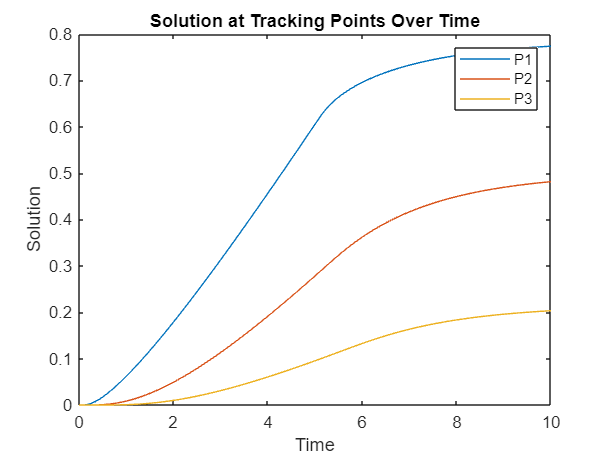

Difference :


                    t=2.5                   t=5                    t=7.5                   t_max        
             ___________________    ____________________    ____________________    ____________________

    u(p1)    0.00357812089415604    0.000635702483394507    0.000849238776170269     0.00140963106034131
    u(p2)    0.00294744352922795     0.00311850518864226     0.00214080027929692    0.000946291020351597
    u(p3)    0.00128692017970666     0.00247922965197026     0.00293000102999066     0.00241441123702418



Max diam h = 0.23582


Solution at tracking points at t=2.5, 5, 7.5, t = t_max:


                   t=2.5                  t=5                  t=7.5                t_max      
             __________________    __________________    _________________    _________________

    u(p1)     0.247433038069295      0.60610289543134    0.745559115215051     0.77490864892628
    u(p2)    0.0794235662784956      0.27668035630411    0.433702043334819    0.480876512127503
    u(p3)    0.0190938339871284    0.0937256702885721    0.172538407881037    0.201497636995292



Difference :


                    t=2.5                    t=5                    t=7.5                   t_max        
             ____________________    ____________________    ____________________    ____________________

    u(p1)     0.00399403806929541     0.00142539543134024    6.23152150509565e-05    0.000218651073720211
    u(p2)     0.00219486627849563      0.0015085563041104    0.000839043334819156    0.000325112127503357
    u(p3)    0.000790133987128402    0.000901570288572073    0.000885807881036649     0.00062543699529205



Max diam h = 0.12745


Solution at tracking points at t=2.5, 5, 7.5, t = t_max:


                   t=2.5                  t=5                  t=7.5                t_max      
             __________________    __________________    _________________    _________________

    u(p1)     0.247476377064773      0.60616617233367    0.745655890331561    0.775102766700267
    u(p2)     0.079216490439967      0.27621666263192    0.433311948103299    0.480692233322104
    u(p3)    0.0189695428959332    0.0933287295769459    0.172038653647438    0.201088342029254



Difference :


                    t=2.5                    t=5                    t=7.5                   t_max        
             ____________________    ____________________    ____________________    ____________________

    u(p1)     0.00403737706477303     0.00148867233366978     0.00015909033156114     2.4533299733398e-05
    u(p2)       0.001987790439967     0.00104486263192016    0.000448948103298596    0.000140833322103739
    u(p3)    0.000665842895933234    0.000504629576945886    0.000386053647438461    0.000216142029253741



Max diam h = 0.06849


Solution at tracking points at t=2.5, 5, 7.5, t = t_max:


                   t=2.5                  t=5                  t=7.5                t_max      
             __________________    __________________    _________________    _________________

    u(p1)     0.247485916790095      0.60619279655197    0.745704616499948    0.775176025424233
    u(p2)    0.0791658883352287     0.276108871772538    0.433230068089064    0.480663960380626
    u(p3)    0.0189363780545891    0.0932208996446846    0.171898981718442    0.200969167678424



Difference :


                    t=2.5                    t=5                    t=7.5                   t_max        
             ____________________    ____________________    ____________________    ____________________

    u(p1)     0.00404691679009522     0.00151529655196991    0.000207816499948277    4.87254242333979e-05
    u(p2)     0.00193718833522868    0.000937071772537823     0.00036706808906356    0.000112560380625792
    u(p3)    0.000632678054589095    0.000396799644684628    0.000246381718441824     9.6967678423765e-05



Max diam h = 0.034017


Solution at tracking points at t=2.5, 5, 7.5, t = t_max:


                   t=2.5                  t=5                 t=7.5                t_max      
             __________________    _________________    _________________    _________________

    u(p1)     0.247481403110072    0.606185839926826    0.745704065716959    0.775182704102216
    u(p2)     0.079150747394274     0.27607639565728    0.433203727216303     0.48065150159032
    u(p3)    0.0189275051275142    0.093193108624204    0.171864022799363    0.200940055541104



Difference :


                    t=2.5                   t=5                   t=7.5                   t_max        
             ___________________    ___________________    ____________________    ____________________

    u(p1)    0.00404240311007159    0.00150833992682609     0.00020726571695906     5.5404102215828e-05
    u(p2)    0.00192204739427397    0.00090459565728046    0.000340727216303016    0.000100101590319923
    u(p3)    0.00062380512751423    0.00036900862420404    0.000211422799363342    6.78555411036952e-05



Max diam h = 0.016835


b2_chol = zeros(num_nodes,1);
b2_j = zeros(num_nodes,1);
H_new= H;
u_chol2= zeros(num_nodes,1);
u_j2= zeros(num_nodes,1);
H_new(boundary_conditions(:,1),:)=0;
b2_chol = b2_chol- H_new(:,boundary_conditions(:,1))*boundary_conditions(:,2);
b2_j=b2_j- H_new(:,boundary_conditions(:,1))*boundary_conditions(:,2);
b2_chol(boundary_conditions(:,1))=boundary_conditions(:,2);
b2_j(boundary_conditions(:,1))=boundary_conditions(:,2);
H_new(:,boundary_conditions(:,1))=0;
for c=1: size(boundary_conditions,1)
      H_new(boundary_conditions(c,1),boundary_conditions(c,1))=1;
          
end
L = ichol(H_new);
%J=diag(diag(H_new));
for d =1:size(H,1)
    J(d,d)=H(d,d);
end
[u_steady, flag_chol, relres_chol, iter, resvec_chol]=pcg(H_new,b2_chol, 1e-9, 1000, L, L');
[u_steady_j, flag_j, relres_j, iter_j, resvec_j]=pcg(H_new,b2_j, 1e-9, 2000, J);

figure;
cr = triangulation(topology, coordinates(:,1), coordinates(:,2), u_steady);
trisurf(cr, 'FaceColor', 'interp', 'EdgeColor', [0.8 0.8 0.8], 'EdgeAlpha', 0.4); % Colore grigio chiaro e semi-trasparente per i bordi
%trisurf(cr, 'FaceColor', 'interp', 'EdgeColor', [0.9 0.9 0.9], 'LineWidth', 0.1, 'EdgeAlpha', 0.1);
axis equal tight; 
view(3); 
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Solution u');
title('FEM Simulation Steady State, Cholesky ');
colorbar;


%ERROR ANALYSIS
epsilon=0;
[ f] = nodal_areas(topology, coordinates);
for i=1:size(coordinates, 1)
     epsilon=epsilon+((u_steady(i)-sol(i))^2)*(f(i));
end
Errore(mesh) = (epsilon)^(0.5);


data_displayed = [
    0.2434390, 0.6046775, 0.7454968, 0.7751273;
    0.0772287, 0.2751718, 0.4328630, 0.4805514;
    0.0183037,  0.0928241, 0.1716526, 0.2008722

];

% Difference between given data and the ones obtained stored in T
differenza = abs(T{:,:} - data_displayed);
Differenza_T = array2table(differenza, 'VariableNames', T.Properties.VariableNames, 'RowNames', row_names);
disp('Difference :');
disp(Differenza_T);

h_current = 0;

% Iterating on all the elements K in the triangulation
for k = 1:size(topology, 1)
    % Find indices of the nodes composing element K
    nodes_indices = topology(k, :) - 1; 
    x_K = coordinates(nodes_indices + 1, 1); % +1 for one-based indexing in MATLAB
    y_K = coordinates(nodes_indices + 1, 2);
    distances_K = zeros(length(nodes_indices), length(nodes_indices));
   % Calculate all pairwise distances within the element K
    for i = 1:length(nodes_indices)
        for j = 1:length(nodes_indices)
            if i ~= j % No need to calculate distance from a point to itself
                distances_K(i, j) = sqrt((x_K(i) - x_K(j))^2 + (y_K(i) - y_K(j))^2);
            end
        end
    end
    hK = max(distances_K(:)); % The diameter of the element is the max distance
    h_current = max(h_current, hK); 
end

h(mesh) = h_current;
disp(['Max diam h = ', num2str(h_current)]);

   ratio_c(1)=0;
        if mesh>=2
            ratio_c(mesh)= (Errore(mesh-1)/Errore(mesh))*((h(mesh))/(h(mesh-1)))^2;
        end

   %convergence plot for pcg, both preconditioners
   figure;
   semilogy(0:iter,resvec_chol,'-o');
   xlabel('Number of iterations N')
   ylabel('Residual norm')
   title('Cholesky preconditioner'); 
   hold on;
   semilogy(0:iter_j,resvec_j,'-*');
   xlabel('Number of iterations N')
   ylabel('Residual norm')
   title('Jacobi vs Cholesky preconditioner'); 
   hold off;
end

mesh = [0 1 2 3 4]';
NT = table(mesh,Errore',h', ratio_c');
NT.Properties.VariableNames = {'mesh','Error','h', 'ratio'};
disp(NT);

    mesh           Error                    h                   ratio      
    ____    ____________________    __________________    _________________

     0       0.00228718901516191     0.235818204905456                    0
     1      0.000605626190129826     0.127454840117735     1.10320295263748
     2      0.000146415843662186    0.0684896189965747     1.19440994018788
     3      3.68694290364445e-05    0.0340171947553465    0.979645966085787
     4      8.78090077740822e-06    0.0168349638012008     1.02838260813652



Functions

function [H, M] = compute_local_matrices(topology, coordinates)
    num_nodes = size(coordinates, 1);
    num_elements = size(topology, 1);
    H = zeros(num_nodes); % Global stiffness matrix
    M = zeros(num_nodes); % Global mass matrix
    
    for e = 1:num_elements
        element_nodes = topology(e, :);
     % Node coordinates for the current element
        xi = coordinates(element_nodes(1), 1);
        yi = coordinates(element_nodes(1), 2);
        xj = coordinates(element_nodes(2), 1);
        yj = coordinates(element_nodes(2), 2);
        xm = coordinates(element_nodes(3), 1);
        ym = coordinates(element_nodes(3), 2);
       % Calculate the area of the triangle (Delta)
        delta = 0.5 * det([1, xi, yi; 1, xj, yj; 1, xm, ym]);
       % Calculate coefficients for the stiffness matrix
        ai = xj*ym - xm*yj;
        bi = yj - ym;
        ci = xm - xj;
        aj = xm*yi - xi*ym;
        bj = ym - yi;
        cj = xi - xm;
        am = xi*yj - xj*yi;
        bm = yi - yj;
        cm = xj - xi;
        % Local stiffness matrix Hloc
        Hloc = (1/(4 *delta)) * [bi*bi+ci*ci, bi*bj+ci*cj, bi*bm+ci*cm; 
                                 bj*bi+cj*ci, bj*bj+cj*cj, bj*bm+cj*cm; 
                                 bm*bi+cm*ci, bm*bj+cm*cj, bm*bm+cm*cm];
        
        % Local mass matrix Mloc
        Mloc = (delta / 12) * [2, 1, 1; 1, 2, 1;  1, 1, 2];
        
        % Assemble local matrices into global matrices
        for i = 1:3
            for j = 1:3
                H(element_nodes(i), element_nodes(j)) = H(element_nodes(i), element_nodes(j)) + Hloc(i, j);
                M(element_nodes(i), element_nodes(j)) = M(element_nodes(i), element_nodes(j)) + Mloc(i, j);
            end
        end
    end
end
        
function [f] = nodal_areas(topology, coordinates)
    num_elements = size(topology, 1);
    num_nodes = size(coordinates, 1); 
    f = zeros(num_nodes, 1); 
    element_areas = zeros(num_elements, 1);
    
    % Calcolo dell'area per ogni elemento una volta sola
    for j = 1:num_elements
        nodes = topology(j, :);
        x = coordinates(nodes, 1);
        y = coordinates(nodes, 2);
        element_areas(j) = 0.5 * abs(det([1, x(1), y(1); 1, x(2), y(2); 1, x(3), y(3)]));
    end
    
    % Assegnazione dell'area a ciascun nodo
    for j = 1:num_elements
        nodes = topology(j, :);
        for k = 1:3
            f(nodes(k)) = f(nodes(k)) + element_areas(j) / 3;
        end
    end
end